# Blockkurs Tutorial 2: Digitale Signalverarbeitung

Copyright © 2024

Authors: J. Christopher Edgar and Gregory A. Miller

*The authors of the digital signal processing courseware are indebted to Prof. Bruce Carpenter (University of Illinois Urbana-Champaign). Bruce inspired the creation of this courseware, consulted with the authors throughout its development, and provided the original versions of the code and text for several sections, including those on complex numbers and normal distributions. Dr. J. Christohper Edgar is Professor of Radiology at the University of Pennsylvania and the Children’s Hospital of Philadelphia. Dr. Gregory A. Miller is Professor of Psychology at the University of California Los Angeles and University of Illinois Urbana-Champaign. The original courseware was written in Python and run using Juypter, available via GitHub (****LINK****). The adaptation of sections of this courseware to MATLAB was completed by Arne Hansen.*

**1. Wichtige Konzepte zu digitalen Signalen**

**    1.1 Sinuswellen**

    **1.2 Frequenz**

    **1.3 Amplitude**

    **1.4 Phase**

**3. Daten und Ordner**

## **1. Wichtige Konzepte zu digitalen Signalen**

Dieses Tutorial behandelt die Grundlagen der digitalen Signalverarbeitung, beginnend mit den grundlegenden Konzepten von digitalen Signalen. Wir werden anhand von **Sinuswellen** lernen, was die **Frequenz**, **Amplitude** und **Phase** eines Signals sind.

## **1.1 Sinuswellen**

Eine Sinuswelle ist eine fundamentale Signalform, die durch die Gleichung y(t) = A * sin(2 * pi * f * t + phase) beschrieben wird. Hierbei ist:

    **A** die Amplitude,

    **f** die Frequenz,

    **phase** die Phase, und

    **t** die Zeit.

Das sieht nun erst mal kompliziert aus. Wir werden uns jedoch im Folgenden vereinzelt mit den Bestandteilen dieser Gleichung auseinandersetzen.

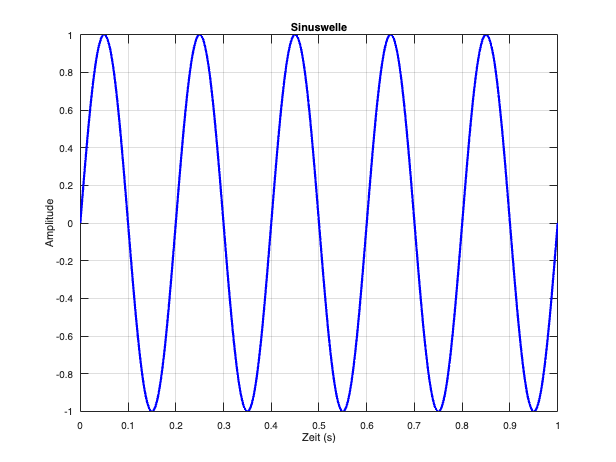


% MATLAB-Code zur Visualisierung einer Sinuswelle
fs = 1000; % Abtastrate (Hz)
t = 0:1/fs:1; % Zeitvektor von 0 bis 1 Sekunde mit Schrittweite 1/fs
f = 5; % Frequenz der Sinuswelle (Hz)
A = 1; % Amplitude
phi = 0; % Phase (Radianten)

y = A * sin(2 * pi * f * t + phi);

figure;
plot(t, y, 'b', 'LineWidth', 2);
title('Sinuswelle');
xlabel('Zeit (s)');
ylabel('Amplitude');
grid on;

## **1.2 Frequenz**

Die Frequenz eines Signals beschreibt, wie oft eine Schwingung pro Sekunde auftritt. Sie wird in Hertz (Hz) gemessen.

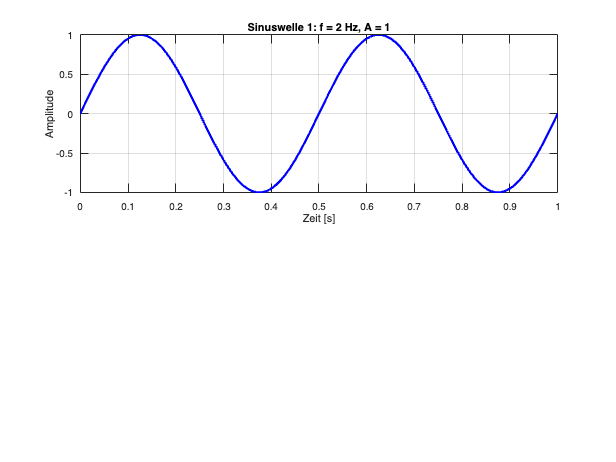

%% Parameter festlegen
f1 = 2; % Frequenz der ersten Sinuswelle in Hz
A1 = 1; % Amplitude der ersten Sinuswelle
phi1 = 0; % Phasenverschiebung der ersten Sinuswelle in Radiant

fs = 100; % Abtastfrequenz in Hz
t = 0:1/fs:1; % Zeitvektor von 0 bis 2 Sekunden in Schritten von 1/fs

%% Sinuswellen berechnen
y1 = A1 * sin(2 * pi * f1 * t + phi1); % Erste Sinuswelle

%% Visualisierung
figure;

% Erste Sinuswelle plotten
subplot(2, 1, 1);
plot(t, y1, 'b', 'LineWidth', 2);
xlabel('Zeit [s]', 'FontSize', 12);
ylabel('Amplitude', 'FontSize', 12);
title('Sinuswelle 1: f = 2 Hz, A = 1', 'FontSize', 14);
grid on;

## 1.3 Amplitude

Die Amplitude eines Signals gibt die maximale Auslenkung des Signals von seiner Gleichgewichtslage an. Sie bestimmt, wie "stark" das Signal ist.

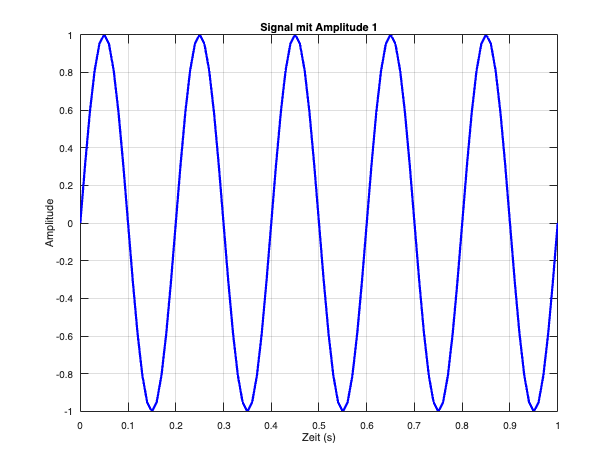


% MATLAB-Code zur Visualisierung von Signalen mit unterschiedlicher Amplitude
A1 = 1;

y1 = A1 * sin(2 * pi * f * t);

figure;
plot(t, y1, 'b', 'LineWidth', 2);
title('Signal mit Amplitude 1');
xlabel('Zeit (s)');
ylabel('Amplitude');
grid on;

## 1.4 Phase

Die Phase eines Signals beschreibt die Verschiebung der Sinuswelle entlang der Zeitachse. Sie wird in Radianten angegeben.

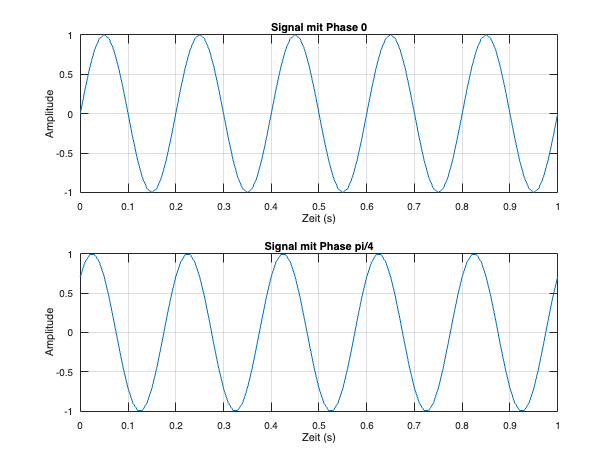


% MATLAB-Code zur Visualisierung von Signalen mit unterschiedlicher Phase
phi1 = 0; % Phase 0 Radianten
phi2 = pi/4; % Phase pi/4 Radianten

y1 = sin(2 * pi * f * t + phi1);
y2 = sin(2 * pi * f * t + phi2);

figure;
subplot(2,1,1);
plot(t, y1);
title('Signal mit Phase 0');
xlabel('Zeit (s)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(t, y2);
title('Signal mit Phase pi/4');
xlabel('Zeit (s)');
ylabel('Amplitude');
grid on;

## **2.X Daten und Ordner**

Wir haben bis jetzt ausschliesslich mit simulierten Daten, bzw. einfachen Beispielen gearbeitet. Im Blockkurs werden wir jedoch mit echten EEG-Datensätzen arbeiten. Damit diese Daten in MATLAB benutzt werden können, muss man MATLAB klar machen, in welchem Ordner auf dem Computer die Daten liegen. Daraufhin kann man die Daten laden.

Bevor du mit dem Programmieren beginnst, stelle sicher, dass deine Daten in einem gut organisierten Ordner gespeichert sind. MATLAB arbeitet standardmässig mit dem aktuellen Ordner, also speichere Skripte und Daten am besten dort, um Verwirrung zu vermeiden.

**am schluss pfade laden:**

%% Pfade setzen
pwd

ans = '/Users/Arne/Documents/GitHub'

%Pfad zu den Daten
%pathToData='C:\Users\mtroen\Dropbox\AA_Teaching\Blockkurs_Auswertung_neurophysiologische_Experimente\FS_2024\Praxis\data';
%pathToData='data'

%Pfad zu EEGlab
%addpath('eeglab2021.1')

%% EEG daten laden
%load( [pathToData  '/sub-002.mat'] );

%load in "EEG". EEG ist einem neuen format von Daten: "struct"

%for i=2:4
 %  allEEG{i}=  load( [pathToData  '/sub-00' num2str(i) '.mat'] );
%end

%% Finaler check: Signal processing toolbox installiert?